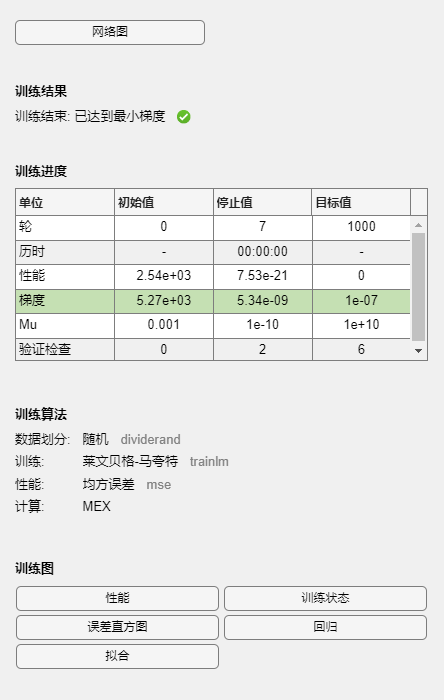

clc,clear
% 加载数据
data = readtable('rescue_robot_data_1.csv');

% 特征和目标变量
X = table2array(data(:, {'time_to_complete', 'successful_rescues', 'missed_rescues', 'collisions'}));
y = data.completion_rate;

% 检查数据是否有 NaN 值
if any(isnan(X(:))) || any(isnan(y))
    error('数据包含 NaN 值，请检查数据生成步骤。');
end

% 数据标准化
X = zscore(X);

% 拆分训练集和测试集
rng(42); % 设置随机数种子以确保可重复性
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
X_train = X(training(cv), :);
X_test = X(test(cv), :);
y_train = y(training(cv));
y_test = y(test(cv));
% 线性回归
mdl_lr = fitlm(X_train, y_train);
y_pred_lr = predict(mdl_lr, X_test);
mae_lr = mean(abs(y_test - y_pred_lr));
mse_lr = mean((y_test - y_pred_lr).^2);

% 决策树
mdl_tree = fitrtree(X_train, y_train);
y_pred_tree = predict(mdl_tree, X_test);
mae_tree = mean(abs(y_test - y_pred_tree));
mse_tree = mean((y_test - y_pred_tree).^2);

% 支持向量机
mdl_svm = fitrsvm(X_train, y_train);
y_pred_svm = predict(mdl_svm, X_test);
mae_svm = mean(abs(y_test - y_pred_svm));
mse_svm = mean((y_test - y_pred_svm).^2);

% 人工神经网络
net = fitnet(10); % 10个隐藏层神经元
net = train(net, X_train', y_train');

y_pred_nn = net(X_test')';
mae_nn = mean(abs(y_test - y_pred_nn));
mse_nn = mean((y_test - y_pred_nn).^2);

% 打印结果
fprintf('Linear Regression - MAE: %f, MSE: %f\n', mae_lr, mse_lr);

Linear Regression - MAE: 1.219750, MSE: 1.809174


fprintf('Decision Tree - MAE: %f, MSE: %f\n', mae_tree, mse_tree);

Decision Tree - MAE: 4.188401, MSE: 29.378896


fprintf('Support Vector Machine - MAE: %f, MSE: %f\n', mae_svm, mse_svm);

Support Vector Machine - MAE: 1.995184, MSE: 5.329097


fprintf('Neural Network - MAE: %f, MSE: %f\n', mae_nn, mse_nn);

Neural Network - MAE: 3.716552, MSE: 23.630425


% 特征选择使用随机森林重要性
mdl_rf = TreeBagger(100, X_train, y_train, 'Method', 'regression', 'OOBPredictorImportance', 'on');
importance = mdl_rf.OOBPermutedPredictorDeltaError;
[~, sorted_idx] = sort(importance, 'descend');
disp('Feature Importance (sorted):');

Feature Importance (sorted):


disp(sorted_idx);

     3     2     1     4




% 使用前两个重要特征进行训练和预测
X_train_fs = X_train(:, sorted_idx(1:2));
X_test_fs = X_test(:, sorted_idx(1:2));

% 重新训练和评估线性回归模型
mdl_lr_fs = fitlm(X_train_fs, y_train);
y_pred_lr_fs = predict(mdl_lr_fs, X_test_fs);
mae_lr_fs = mean(abs(y_test - y_pred_lr_fs));
mse_lr_fs = mean((y_test - y_pred_lr_fs).^2);
fprintf('Linear Regression with Feature Selection - MAE: %f, MSE: %f\n', mae_lr_fs, mse_lr_fs);

Linear Regression with Feature Selection - MAE: 1.046250, MSE: 1.357272


|===================================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |  Standardize |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |      5.2403 |     0.11969 |      5.2403 |      5.2403 |      0.15905 |       3.6632 |       83.769 |        false |
|    2 | Accept |      5.2403 |    0.017943 |      5.2403 |      5.2403 |    0.0028232 |    0.0048162 |       1644.9 |         true |
|    3 | Accept |      5.2584 |    0.014998 |      5.2403 |      5.2403 |    0.0051518 |    0.0028456 |     0.096188 |        false |
|    4 | Accept |      5.2579 |    0.015282 |      5.2403 |   

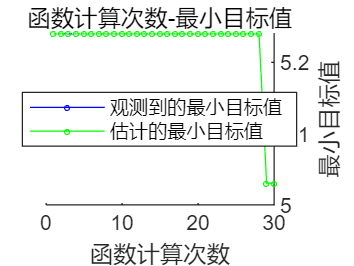


% 超参数调优使用网格搜索
svm_template = templateSVM('KernelFunction', 'rbf');
mdl_svm_tuned = fitrsvm(X_train_fs, y_train, 'KernelFunction', 'rbf', 'OptimizeHyperparameters', 'auto');

y_pred_svm_tuned = predict(mdl_svm_tuned, X_test_fs);
mae_svm_tuned = mean(abs(y_test - y_pred_svm_tuned));
mse_svm_tuned = mean((y_test - y_pred_svm_tuned).^2);
fprintf('Tuned Support Vector Machine with Feature Selection - MAE: %f, MSE: %f\n', mae_svm_tuned, mse_svm_tuned);

Tuned Support Vector Machine with Feature Selection - MAE: 3.090908, MSE: 18.991195
